clc;clear;close all;

## 现场参数设置

ans = 1

delte first line: Q
    "fix missed: lines with all zeros:8"
    "fix missed: lines with all zeros:9"
    "fix missed: lines with all zeros:10"
    "fix missed: lines with all zeros:11"
    "fix missed: lines with all zeros:12"
    "fix missed: lines with all zeros:13"
    "fix missed: lines with all zeros:14"
    "fix missed: lines with all zeros:15"
    "fix missed: lines with all zeros:16"
    "fix missed: lines with all zeros:17"
    "fix missed: lines with all zeros:18"
    "fix missed: lines with all zeros:19"
    "fix missed: lines with all zeros:20"
    "fix missed: lines with all zeros:21"
    "fix missed: lines with all zeros:22"
    "fix missed: lines with all zeros:23"
    "fix missed: lines with all zeros:24"
    "fix missed: lines with all zeros:25"
    "fix missed: lines with all zeros:26"
    "fix missed: lines with all zeros:27"
    "fix missed: lines with all zeros:28"
    "fix missed: lines with all zeros:29"
    "fix missed: lines with all zeros:30"
    "fix missed:

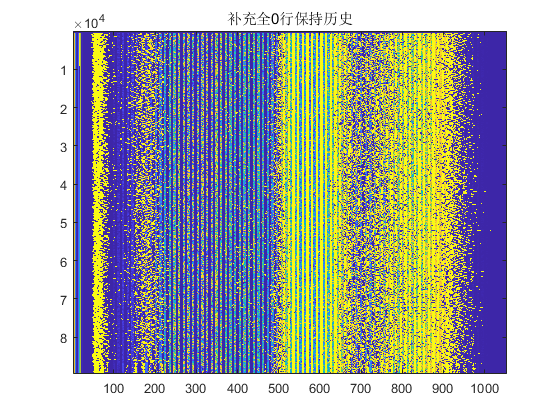

    "all lines with all zeros:7"
    "all lines with all zeros:8"
    "all lines with all zeros:9"
    "all lines with all zeros:10"
    "all lines with all zeros:11"
    "all lines with all zeros:12"
    "all lines with all zeros:13"
    "all lines with all zeros:14"
    "all lines with all zeros:15"
    "all lines with all zeros:16"
    "all lines with all zeros:17"
    "all lines with all zeros:18"
    "all lines with all zeros:19"
    "all lines with all zeros:20"
    "all lines with all zeros:21"
    "all lines with all zeros:22"
    "all lines with all zeros:23"
    "all lines with all zeros:24"
    "all lines with all zeros:25"
    "all lines with all zeros:26"
    "all lines with all zeros:27"
    "all lines with all zeros:28"
    "all lines with all zeros:29"
    "all lines with all zeros:30"
    "all lines with all zeros:31"
    "all lines with all zeros:32"
    "all lines with all zeros:33"
    "all lines with all zeros:34"
    "all lines with all zeros:35"
    "all lines wi

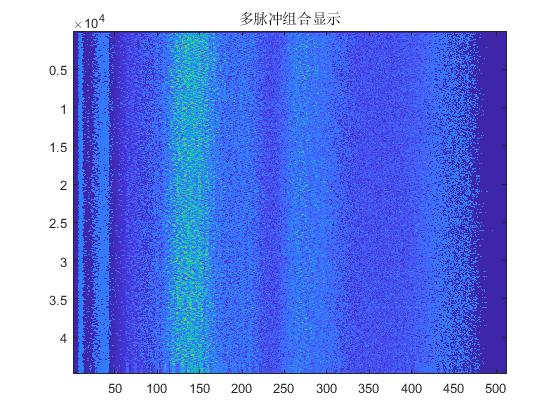

Radar.note = "机械硬盘（HDD），Z字扫描";

filepath = "C:\Users\HOH\Desktop\lyfile\20240904成像\机械硬盘（HDD）";
filename = "2024_09_04_152348_807084-matlab.txt";

goodlen = 30 + 2*512;
tic
Radar.data = read_log_py(filepath + "\" + filename, goodlen);

toc

历时 24.261382 秒。


Radar.fc_GHz = 116+10/2;
Radar.B_MHz = 10000;
Radar.tr_us = 315;
Radar.fs_MHz = 27/15/2;
Radar.PRF_Hz = 34.48;
Radar.vx_mmps = 40;
Radar.vy_mmps = 0.2;
Radar.x0_mm = 0;
Radar.y0_mm = 0;
Radar.z0_mm = 650;
Radar

Radar = 包含以下字段的 struct :
       note: "机械硬盘（HDD），Z字扫描"
       data: [44828×512 double]
     fc_GHz: 121
      B_MHz: 10000
      tr_us: 315
     fs_MHz: 0.9000
     PRF_Hz: 34.4800
    vx_mmps: 40
    vy_mmps: 0.2000
      x0_mm: 0
      y0_mm: 0
      z0_mm: 650


数据正确长度：应该包含总计30的协议长度+点数*2。512点时应该为1054

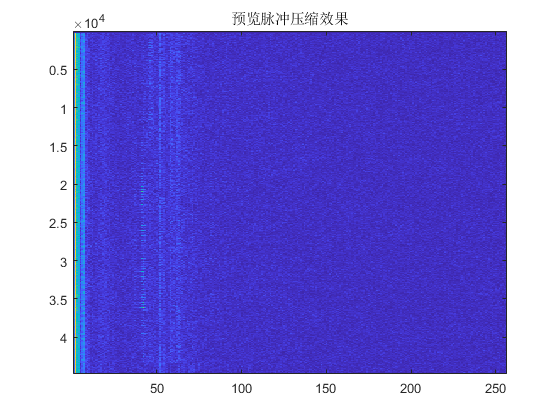

Echo = fft(conj(Radar.data), 512, 2); Echo = Echo(:,1:256);
figure; imagesc(abs(Echo)); title('预览脉冲压缩效果');

## 保存参数

savepath = filepath

savepath = "C:\Users\HOH\Desktop\lyfile\20240904成像\机械硬盘（HDD）"

savename = split(filename,'-'); savename = savename(1);
save(savepath + "\" + savename + ".mat", 'Radar')

## 函数

function frame_data = read_log_py(filename, goodlen)
%% 读取数据
framegood = readmatrix(filename);
framegood = framegood(:,1:goodlen);
rowsWithNaN = any(isnan(framegood), 2);
framegood = framegood(~rowsWithNaN, :);
rowsnotdata = (framegood(:,7)~=68) | (framegood(:,13)~=1 & framegood(:,13)~=2) | ...
                max((framegood(:,end-1:end)~=[13 10]).').' | max((framegood(:,1:4)~=[170 170 187 204]).').';
sum(rowsnotdata)
framegood(rowsnotdata,:) = [];

%% 确认IQ路组合
if framegood(1,13) == 2
    framegood(1,:) = [];
    disp("delte first line: Q");
end
frameidx_I_Q = framegood(:,6)*256 + framegood(:,5);
diff_frame_idx = diff(frameidx_I_Q);
frameidx_I_Q_bad_idx = find(diff_frame_idx~=1 & diff_frame_idx~=-65535) + 1;
for ii = length(frameidx_I_Q_bad_idx):-1:1
    idx = frameidx_I_Q_bad_idx(ii);
    badnum = diff_frame_idx(idx-1);
    if badnum < 0
        badnum = badnum + 65536;
    end
    framegood = [framegood(1:idx-1,:);zeros(badnum-1,goodlen);framegood(idx:end,:)];
end
zerolines = find(framegood(:,1) == 0);
disp("fix missed: lines with all zeros:" + zerolines);
if mod(size(framegood,1),2) == 1
    framegood(end,:) = [];
    disp("delte last line: I");
end
figure;imagesc(abs(framegood)); title("补充全0行保持历史")
for ii = 1:length(zerolines)
    idx = zerolines(ii);
    if mod(idx,2) == 1
        framegood(idx+1,:) = zeros(1,goodlen);
    else
        framegood(idx-1,:) = zeros(1,goodlen);
    end
end
zerolines = find(framegood(:,1) == 0);
disp("all lines with all zeros:" + zerolines);
%% 尝试进行分析
datagood = (goodlen - 30) / 2;
frontnum = 24+1;
% 24长度的头，点数*2的数据，6长度的尾
% 向量化新版
frame_I_data = framegood(1:2:end,frontnum:frontnum+datagood*2-1);
frame_Q_data = framegood(2:2:end,frontnum:frontnum+datagood*2-1);
frame_I_int16 = frame_I_data(:,1:2:end) + 256*frame_I_data(:,2:2:end);
frame_Q_int16 = frame_Q_data(:,1:2:end) + 256*frame_I_data(:,2:2:end);
idx = (frame_I_int16>=2^15); frame_I_int16(idx) = frame_I_int16(idx)-2^16;
idx = (frame_Q_int16>=2^15); frame_Q_int16(idx) = frame_Q_int16(idx)-2^16;

frame_data = frame_I_int16 + 1j * frame_Q_int16;
%frame_data是保存在dec中的int16，要转成uint16
%认为0~2^15 - 1的可以直接采用
%2^15~2^16 实际数值是-(2^16-num)
% figure; plot(db(abs(frame_data(fix(size(frame_data,1)/2),:)))); title('尝试中间行显示db'); xlim([1 512]);
% figure; plot(abs(frame_data(fix(size(frame_data,1)/2),:))); title('尝试中间行显示-线性'); xlim([1 512]);
% figure; imagesc(db(abs(frame_data))); title("多脉冲组合显示db")
figure; imagesc((abs(frame_data))); title("多脉冲组合显示")
% figure; plot(max(abs(frame_data(:,250:end)).')); title("脉冲中最强的（没有DC）");
end